x =    0.500000000000000   0.450000000000000   0.400000000000000   0.350000000000000   0.300000000000000   0.250000000000000   0.200000000000000   0.150000000000000   0.100000000000000   0.050000000000000


y =          406         472         540         613         690         777         872         980        1108        1274


p = 	1.0e+03 *

   2.116666666666670  -3.022106060606061   1.400550000000000


n = 	1.0e+03 *

   0.418663636363637   0.469227272727273   0.530374242424243   0.602104545454546   0.684418181818182   0.777315151515152   0.880795454545454   0.994859090909091   1.119506060606061   1.254736363636364


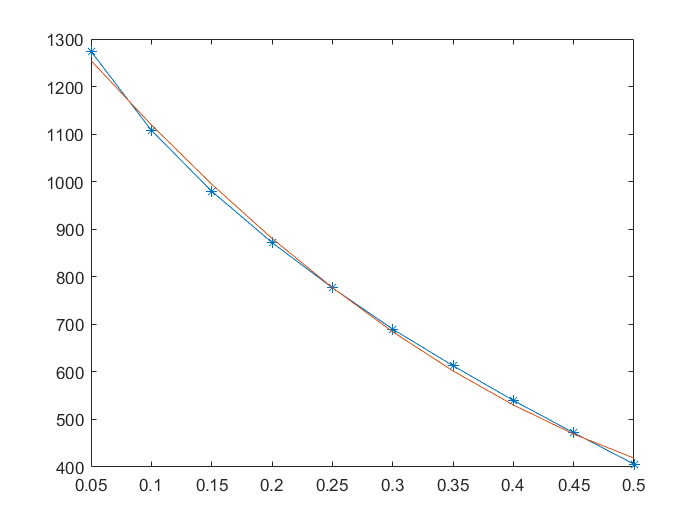

2116.667 x^2 + -3022.106 x + 1400.550

figure(1)


x = 0.5:-0.05:0.05

y = [406, 472, 540, 613, 690, 777, 872, 980, 1108, 1274]

k = [53.3456, 49.4536, 46.2361, 43.3707, 40.8808, 38.5298, 36.3696, 34.3188, 32.2822, 30.1022]

plot(x, y, '*-'); hold on

p = polyfit(x, y, 2)

pe = p(1) * x.^2 + p(2) * x + p(3)

plot(x, pe)

fprintf('%.3f x^2 + %.3f x + %.3f\n', p(1), p(2), p(3))

hold off

figure(2)

plot(x, k, '*-'); hold on

q = polyfit(x, k, 2)

ke = q(1) * x.^2 + q(2) * x + q(3)

plot(x, ke)

fprintf('%.3f x^2 + %.3f x + %.3f\n', q(1), q(2), q(3))

hold off
